# Figure 7: the spatial precision show non monotonical effect to the network capacity

6 - 4

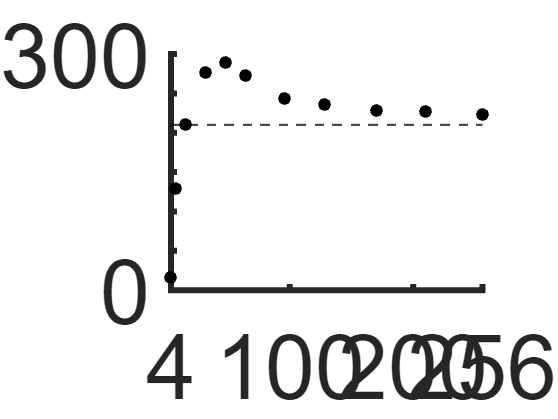

clear; clc;
load_dir = read_output_dir() + "/Fig7";
load(fullfile(load_dir, "CapN.mat"))

[N_network, b] = sort(N_network);
cap_network = cap_network(b);
aux_mat = [N_network; cap_network];
plot(N_network, cap_network, "k.", "MarkerSize", 25)
box off
yline(210, "k--", "LineWidth", 1.5)
axis tight
ylim([0, 300])
xlim([4, 256])
xticks([4, 100, 200, 256])
yticks([0:50:300])
yticklabels([0, "", "", "", "", "", 300])
fig_config(50)